修改尝试

尝试一下一直使用连续函数，现在已经确定是c2d的问题，且目前c2d的所有方法都无法取得良好的效果，所有方法的bode图都几乎没有重合的地方，所以希望先用连续函数来验证传递函数的正确性

load('stabilitycanshu.mat');
dt = 1/1024;

P = 1.5;
I = 45;
D = 1e-8;
N = 100;
s = tf('s');
Gp0 = P+I/s+D*N/(1+N/s)

Gp0 =
 
  1.5 s^2 + 195 s + 4500
  ----------------------
       s^2 + 100 s
 
Continuous-time transfer function.
Model Properties


Gp = [Gp0,0;0,Gp0]

Gp =
 
  From input 1 to output...
       1.5 s^2 + 195 s + 4500
   1:  ----------------------
            s^2 + 100 s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       1.5 s^2 + 195 s + 4500
   2:  ----------------------
            s^2 + 100 s
 
Continuous-time transfer function.
Model Properties


然后是作动器传递函数G

%sys_ss = ss(A,B,C,D);
sys_ss = ss(A_cplant,B_cplant,C_cplant,D_cplant);
G = tf(sys_ss)

G =
 
  From input 1 to output...
                  2165 s^2 + 2.857e06 s + 9.232e08
   1:  ------------------------------------------------------
       s^4 + 896.3 s^3 + 4.279e05 s^2 + 7.107e07 s + 1.069e09
 
                 349.9 s^2 + 4.617e05 s + 1.492e08
   2:  ------------------------------------------------------
       s^4 + 896.3 s^3 + 4.279e05 s^2 + 7.107e07 s + 1.069e09
 
  From input 2 to output...
                       4.539e06 s + 8.557e07
   1:  ------------------------------------------------------
       s^4 + 766.5 s^3 + 3.448e05 s^2 + 3.691e07 s + 6.528e08
 
                       1.924e07 s + 6.044e08
   2:  ------------------------------------------------------
       s^4 + 766.5 s^3 + 3.448e05 s^2 + 3.691e07 s + 6.528e08
 
Continuous-time transfer function.


计算Gp与G的传递函数

现在找到了解决方案，只要将传递函数转换为zpk形式即可

先将连续传递函数转换为zpk形式，再进行c2d即可，此时bode图正常


$$G_1 =\frac{X_m }{X}=\frac{G_P G_C }{1+G_P G_C }$$


从此处开始，G1是2*2的传递函数，此时输入2输出2

G1 = (eye(2)+Gp*G)\Gp*G

G1 =
 
  From input 1 to output...
            3248 s^33 + 1.881e07 s^32 + 5.336e10 s^31 + 9.852e13 s^30 + 1.326e17 s^29 + 1.38e20 s^28 + 1.152e23 s^27 + 7.88e25 s^26 + 4.488e28 s^25 + 2.149e31 s^24 + 8.702e33 s^23 + 2.991e36 s^22 + 8.733e38 s^21 + 2.165e41 s^20 + 4.551e43 s^19 + 8.082e45 s^18 + 1.208e48 s^17 + 1.512e50 s^16 + 1.577e52 s^15 + 1.363e54 s^14 + 9.699e55 s^13 + 5.652e57 s^12 + 2.679e59 s^11 + 1.026e61 s^10 + 3.148e62 s^9 + 7.656e63 s^8 + 1.453e65 s^7 + 2.104e66 s^6 + 2.242e67 s^5 + 1.656e68 s^4 + 7.561e68 s^3 + 1.606e69 s^2 - 6.317e52 s - 4.293e36
   1:  ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------


%G2 = zpk(G1);
%G2 = c2d(G2,dt);
%G3 = tf(G2);

%G1 = G3;

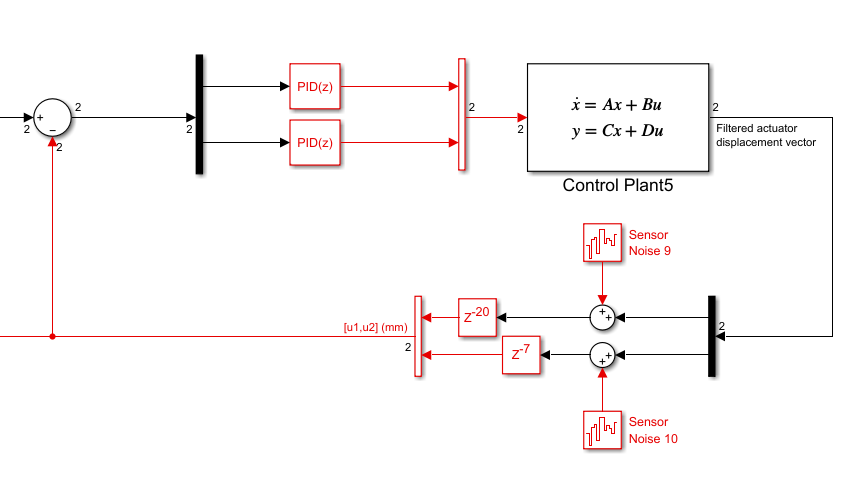

计算物理子结构的反力

为了将xm扩展为5维向量，定义定位矩阵k1，k2，k3

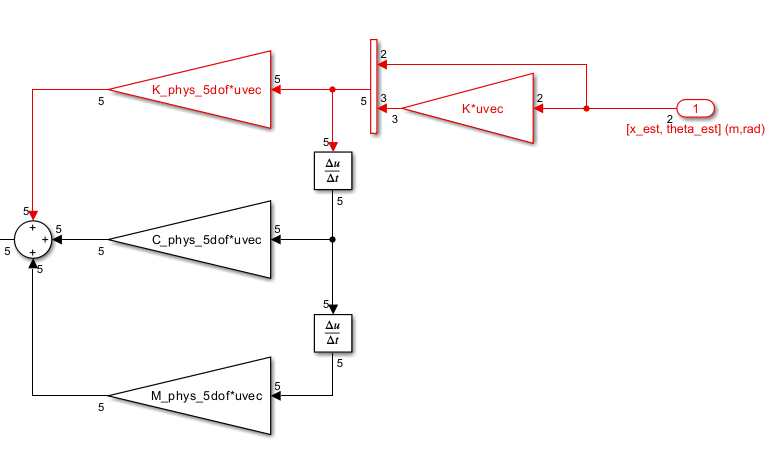

此处k4表示将向量由2维扩展为5维

其中，前两个向量由k1表示


$$\left\lbrack \begin{array}{cc}
1 & \\
 & 1\\
 & \\
 & \\
 & 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\textrm{x1}\\
\textrm{x2}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{x1}\\
\textrm{x1}\\
0\\
0\\
0
\end{array}\right\rbrack$$


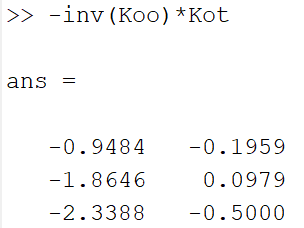


$$\left\lbrack \begin{array}{ccc}
 &  & \\
 &  & \\
1 &  & \\
 & 1 & \\
 &  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
-0\ldotp 95 & -0\ldotp 20\\
-1\ldotp 86 & 0\ldotp 10\\
-2\ldotp 34 & -0\ldotp 50
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
 & \\
 & \\
-0\ldotp 95 & -0\ldotp 20\\
-1\ldotp 86 & 0\ldotp 10\\
-2\ldotp 34 & -0\ldotp 50
\end{array}\right\rbrack$$


k1 = zeros(5,2);
k1(1,1) = 1;
k1(2,2) = 1;
k2 = zeros(5,3);
k2(3,1) = 1;
k2(4,2) = 1;
k2(5,3) = 1;


k4 = k1-k2*inv(Koo)*Kot;


$$X_m =k_4 *{\mathrm{G}}_1 X$$


计算反力

经过k4后，输入2输出5维向量

再经过M5dof等计算出5个力，输入5输出5，结合起来就是输入2输出5，定义Gp1为物理子结构传递函数，Gp1输入2，输出5

%z = tf('z',dt)
%s = zpk(s)
%al2 = (4*M_phys_5dof+2*dt*C_phys_5dof+dt^2*K_phys_5dof)\(4*M_phys_5dof);
%fm = ((1-exp(-dt*s))^2*M_phys_5dof*k4*G1*k3/al+(1-exp(-dt*s))*dt*C_phys_5dof*k4*G1*k3+dt^2*K_phys_5dof*k4*G1*k3*exp(-dt*s))/(exp(-dt*s)*dt^2);
Gp1 = s^2*M_phys_5dof*k4+s*C_phys_5dof*k4+K_phys_5dof*k4

Gp1 =
 
  From input 1 to output...
   1:  8.454 s^2 + 352.1 s + 2.324e06
 
   2:  53.56 s + 8.612e05
 
   3:  -0.8445 s^2 - 30.03 s
 
   4:  -0.7627 s^2 - 23.52 s
 
   5:  -0.9567 s^2 - 34.99 s
 
  From input 2 to output...
   1:  33.79 s + 8.612e05
 
   2:  0.8904 s^2 + 95.01 s + 1.086e06
 
   3:  -0.1744 s^2 - 10.39 s - 1.455e-11
 
   4:  0.04006 s^2 + 0.67 s
 
   5:  -0.2045 s^2 - 13.78 s
 
Continuous-time transfer function.


% 使用 prescale 命令对系统进行预缩放
%fm = prescale(fm)

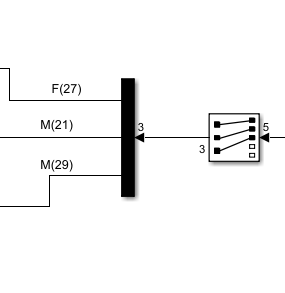

fm只取其中3个，分别定位到27，21，29上

将该反力定位到对应的数值子结构上，定义定位矩阵k5


$$\left\lbrack \begin{array}{cccccc}
\ldotp \ldotp \ldotp  &  &  &  &  & \\
0 & 1 & 0 & 0 & 0 & \\
\ldotp \ldotp \ldotp  &  &  &  &  & \\
1 & 0 & 0 & 0 & 0 & \\
0 & 0 & 0 & 0 & 0 & \\
0 & 0 & 1 & 0 & 0 & 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\textrm{f1}\\
\textrm{f2}\\
\textrm{f3}\\
\textrm{f4}\\
\textrm{f5}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\ldotp \ldotp \ldotp \\
\textrm{f2}\\
\ldotp \ldotp \ldotp \\
\textrm{f1}\\
0\\
\textrm{f3}
\end{array}\right\rbrack$$


k5 = zeros(29,5);
k5(27,1) = 1;
k5(21,2) = 1;
k5(29,3) = 1;

Gp = k5*Gp1;

这样得到的Gp就是29*2，输入2维向量，输出29维向量，且此29维向量中只有21，27，29维不为0

数值子结构，输入29，输出29，此29中只用到了21，27，所以可以看作输入29，输出2

$M_n \ddot{X} +C_n \dot{X} +{\mathrm{K}}_n X=F_n$，显然，Fn：29*1，X：29*1，Mn、Cn、Kn：29*29

建立X与Fn的传递函数


$$G_n =\frac{X}{F_n }=\frac{1}{M_n s^2 +C_n s+{\mathrm{K}}_n }$$


要将X变成2*1维，且按照simulink图所示，要将x21作为xa2，x27作为xa1，则定义k3

         21        27


$$\left\lbrack \begin{array}{cccccc}
\ldotp \ldotp \ldotp  & 0 & \ldotp \ldotp \ldotp  & 1 & 0 & 0\\
\ldotp \ldotp \ldotp  & 1 & \ldotp \ldotp \ldotp  & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ldotp \ldotp \ldotp \\
\textrm{x21}\\
\ldotp \ldotp \ldotp \\
\textrm{x27}\\
\textrm{x28}\\
\textrm{x29}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{x27}\\
\textrm{x21}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\textrm{xa}}_1 \\
{\textrm{xa}}_2 
\end{array}\right\rbrack$$


k3 = zeros(2,29);
k3(1,27) = 1;
k3(2,21) = 1;
Gn1 = (s^2*MNrt+s*CNrt+KNrt)\eye(29,29);
Gn = k3*Gn1

Gn =
 
  From input 1 to output...
                             -1.737e-05 s^41 - 0.5366 s^40 - 7977 s^39 - 7.615e07 s^38 - 5.257e11 s^37 - 2.802e15 s^36 - 1.203e19 s^35 - 4.279e22 s^34 - 1.289e26 s^33 - 3.344e29 s^32 - 7.559e32 s^31 - 1.504e36 s^30 - 2.656e39 s^29 - 4.189e42 s^28 - 5.927e45 s^27 - 7.556e48 s^26 - 8.705e51 s^25 - 9.084e54 s^24 - 8.599e57 s^23 - 7.393e60 s^22 - 5.774e63 s^21 - 4.096e66 s^20 - 2.638e69 s^19 - 1.541e72 s^18 - 8.143e74 s^17 - 3.888e77 s^16 - 1.672e80 s^15 - 6.456e82 s^14 - 2.23e85 s^13 - 6.859e87 s^12 - 1.87e90 s^11 - 4.498e92 s^10 - 9.486e94 s^9 - 1.744e97 s^8 - 2.757e99 s^7 - 3.775e101 s^6 - 4.156e103 s^5 - 4.045e105 s^4 - 2.43e107 s^3 - 1.499e109 s^2 + 1.369e110 s + 9.906e111
   1:  -----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

则，Gn是输入29输出2

结合起来有

$G_{\textrm{cl}} =\frac{X_m }{F}=\frac{G_1 G_n }{1+G_1 G_n G_p }$  $\frac{\left(2,2\right)*\left(2,29\right)}{1+\left(\left.2,2\right)*\left(2,29\right)*\left(29,2\right)\right)}=\frac{\left(2,29\right)}{\left(2,2\right)}$此方程为左除，最后结果为2*29的传递函数

为什么是2*29呢，应该是2*2才对，左除一个2*2，并不能改变矩阵维数，所以，分子处应该存在一个需要右乘的（29，2）的矩阵，但是具体如何定义呢

Gcl = (eye(2)+G1*Gn*Gp)\(G1*Gn)

Gcl =
 
  From input 1 to output...
   1:  NaN
 
   2:  NaN
 
  From input 2 to output...
   1:  NaN
 
   2:  NaN
 
  From input 3 to output...
   1:  NaN
 
   2:  NaN
 
  From input 4 to output...
   1:  NaN
 
   2:  NaN
 
  From input 5 to output...
   1:  NaN
 
   2:  NaN
 
  From input 6 to output...
   1:  NaN
 
   2:  NaN
 
  From input 7 to output...
   1:  NaN
 
   2:  NaN
 
  From input 8 to output...
   1:  NaN
 
   2:  NaN
 
  From input 9 to output...
   1:  NaN
 
   2:  NaN
 
  From input 10 to output...
   1:  NaN
 
   2:  NaN
 
  From input 11 to output...
   1:  NaN
 
   2:  NaN
 
  From input 12 to output...
   1:  NaN
 
   2:  NaN
 
  From input 13 to output...
   1:  NaN
 
   2:  NaN
 
  From input 14 to output...
   1:  NaN
 
   2:  NaN
 
  From input 15 to output...
   1:  NaN
 
   2:  NaN
 
  From input 16 to output...
   1:  NaN
 
   2:  NaN
 
  From input 17 to output...
   1:  NaN
 
   2:  NaN
 
  From input 18 to output...
   1:  NaN
 
   2:  NaN
 
  From inpu

kk1 = [1,0,0;0,0,1];
MP2 = kk1*MP1*kk1'
CP2 = kk1*CP1*kk1'
KP2 = kk1*KP1*kk1'
kk2 = zeros(29,2);
kk2(21,2) = 1;
kk2(27,1) = 1;
Gcl = s^2*MNrt+s*CNrt+KNrt+fm2;

Unrecognized function or variable 'fm2'.

%zero(Gcl)

Gcld = zpk(Gcl);


%% 计算特征值

sym_G = sym(zeros(29,29));

% 转换每个传递函数元素
for i = 1:29
    for j = 1:29
        num_coeffs = Gcl(i,j).Num;
        den_coeffs = Gcl(i,j).Den;
        sym_G(i,j) = poly2sym(num_coeffs, sym('z')) / poly2sym(den_coeffs, sym('z'));
    end
end
Gcl = sym_G

%计算特征方程的行列式
Gcl = simplify(Gcl);
%使用vpa调整精度，默认按照32位计算，不然detGcl计算不出来
Gcl = vpa(Gcl);
detGcl = det(Gcl);
%求解行列式的零点
Gclzero = solve(detGcl);
%计算零点中的最大值
Gclmax = max(abs(Gclzero))